# 3. Considere 4 lancamentos de uma moeda equilibrada. Seja X a variavel aleatoria representativa do numero de coroas observados nos 4 lancamentos

## (a) Estime por simulacao a funcao massa de probabilidade pX(x) da variavel aleatoria X

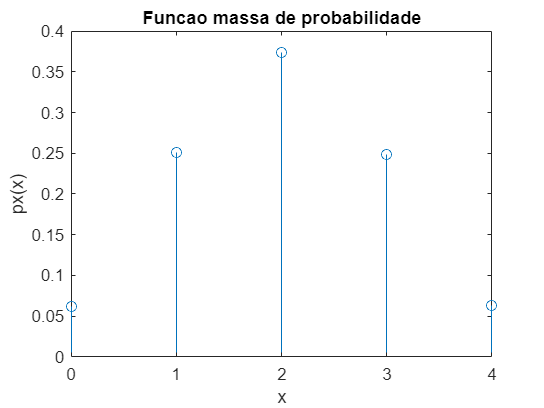

%Funcao massa de probabilidade de X:
pX = zeros(1, 5);
s = 0:4;
N = 1e5; %Numero de experiencias
p = 0.5; %Probabilidade de sair coroa
n = 4;   %numero de lancamentos por experiencia

for i=1 : 5
  k = i-1;
  pX(i) = fMassaProb(N,p,k,n);
end
stem(s,pX), xlabel('x'), ylabel('px(x)'), title('Funcao massa de probabilidade');

## (b) Estime o valor esperado, a variancia e o desvio padrao de X com base em pX(x)


%Valor esperado = somatorio de i=0 ate m de xi * P(X = xi)
E = 0;
for i=1 : 5
  E = E + (i-1) * pX(i);
end


fprintf("E[X]: %d\n",E);

E[X]: 1.996970e+00



%Variancia = E[X^2] - E^2[X]
E2 = 0;
for i=1 : 5
  E2 = E2 + (i-1)^2 * pX(i);
end

var = E2 - E^2;

fprintf("Var(X)= %d\n",var);

Var(X)= 1.003441e+00



%Desvio padrao = sqrt(var(X))
dp = sqrt(var);
fprintf("σX = %d\n",dp);

σX = 1.001719e+00


## c


%% c)

% Esta variavel aleatoria apresenta o comportamento de uma Distribuicao Binomial
%visto que basicamente, temos 4 repeticoes de uma experiencia de Bernoulli (no 
%lancamento de uma moeda, podemos encarar que temos sucesso quando calha coroa
%e insucesso quando calha cara)

%Teoricamente, a expressao da Funcao de massa de prob. de uma variavel Binomial e:

%pX(k) = nCk * p^k * (1-p)^(n-k) = n! / (k! * (n-k)!) * p^k * (1-p)^(n-k)


## d)

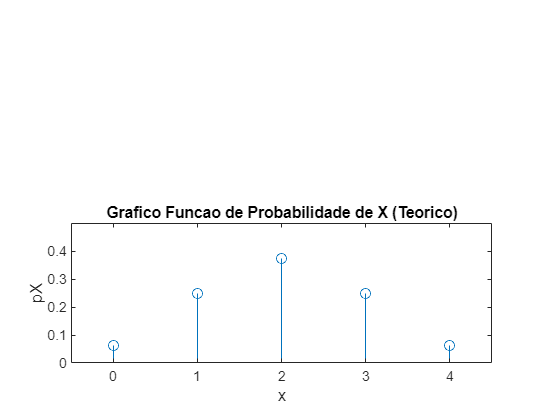

pXTeorica = zeros(1,5);
n = 4;
p = 1/2;

for i=1 : 5
  k = i-1;
  nCk = factorial(n)/(factorial(k) * factorial(n-k));
  pXTeorica(i) = nCk * p^k * (1-p)^(n-k);
end 

subplot(2,2,[3,4]);
x = 0:4;
stem(x,pXTeorica);

axis([-0.5 4.5 0 0.5]);
xlabel('x');
ylabel('pX');
title("Grafico Funcao de Probabilidade de X (Teorico)");

## e

%i)
p = sum(pXTeorica(x>=2));
printf("P(Pelo menos 2 coroas): %d\n",p);

%ii)
p = sum(pXTeorica(x<=1));
printf("P(Ate 1 coroa): %d\n",p);

%iii)
p = sum(pXTeorica(x>=1 & x<=3));
printf("P(Entre 1 e 3 coroas): %d\n",p);